依赖[统一实验分析作图v18.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

同一任务的初始、学会、迁移

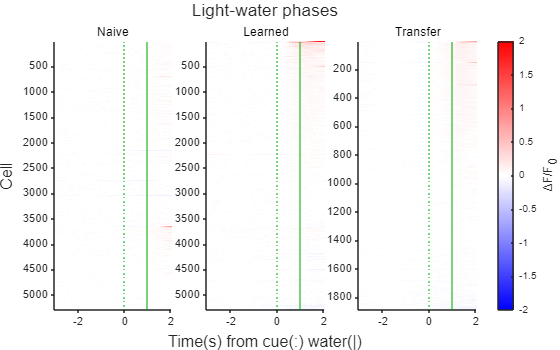

Fig=figure;
Layout=tiledlayout(1,2,TileSpacing='tight',Padding='tight');
Axes(1)=nexttile(Layout,1);
Impl('光水NLT',{8,5,MATLAB.Flags.Narrow},'PPT',1:3,Title='Light-water phases',PcaAx=Axes(1));

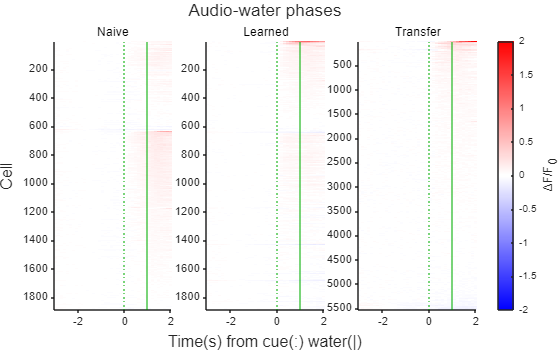

% PcaLegend.Location='southwest';
Axes(2)=nexttile(Layout,2);
Impl('声水NLT',{8,5,MATLAB.Flags.Narrow},'PPT',1:3,Title='Audio-water phases',PcaAx=Axes(2),Legends=["Naive","Learned","Transfer"]);

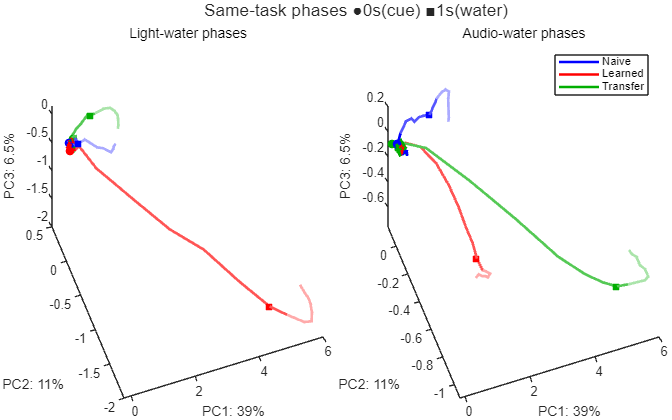

% PcaLegend.Location='southwest';
title(Layout,'Same-task phases ●0s(cue) ■1s(water)');
UniExp.PcaRotate(Axes);
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Amplify,Fig);
print(Fig,TransferLearning.ProjectPath('同任务PCA.png'),'-dpng','-r300');

function PcaLegend=Impl(SheetName,AspectRatio,Target,PCs,options)
arguments
	SheetName
	AspectRatio
	Target
	PCs
	options.Title
	options.PcaAx
	options.Legends
end
import TransferLearning.*
GroupNtats=NtatsFromSheetname(SheetName,Flags.Different_cells_not_handled);
Transfer=UniExp.HeatmapSort(GroupNtats.Transfer);
NaiveLearned=UniExp.NtatsCellStrip(rmfield(GroupNtats,'Transfer'));
NLData=2.^UniExp.HeatmapSort(NaiveLearned).NTATS-1;
Layout=BasicHeatmap({NLData.Naive,NLData.Learned,2.^Transfer.NTATS-1},["Naive","Learned","Transfer"],[0,0,1;1,0,0;0,0.681,0],false,CLim=[-2,2],Flags=UniExp.Flags.SymmetricColormap);
if isfield(options,'Title')
	title(Layout,options.Title);
end
MATLAB.Graphics.FigureAspectRatio(AspectRatio{:});
print(ProjectPath(sprintf('%s.热图.%s.svg',SheetName,Target)),'-dsvg');
[~,NaiveLearned]=UnifiedPcaModel(NaiveLearned);
[~,Transfer]=UnifiedPcaModel(Transfer);
Explained=Transfer.Explained(PCs);
FullNew=~isfield(options,'PcaAx');
if FullNew
	PcaAx={};
	figure;
else
	PcaAx={options.PcaAx};
end
Lines=UniExp.SegmentFadePlot(table(permute(cat(3,NaiveLearned.Score{PCs,:,["Naive","Learned"]},Transfer.Score(PCs,:)),[3,1,2]),GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]),'VariableNames',["Points","Color"]),table([24;32],('os')','VariableNames',["Index","Shape"]),PcaAx{:},PatchArguments={'LineWidth',2});
if isfield(options,'Legends')
	PcaLegend=legend(Lines,options.Legends,Interpreter='none');
end
UniExp.PcAxLabels(table(PCs',Explained,'VariableNames',["Index","Explained"],'RowNames',["X";"Y";"Z"]),PcaAx{:});
if isfield(options,'Title')
	title(PcaAx{:},options.Title);
end
if FullNew
	title('●0s(cue) ■1s(water)');
	MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
	print(ProjectPath(sprintf('%s.PCA.png',SheetName)),'-dpng','-r300');
end
end